% Demo code to divide the image up into 16 pixel by 16 pixel blocks
% and replace each pixel in the block by the median, mean, or standard
% deviation of all the gray levels of the pixels in the block.
%
clc;
clearvars;
close all;
workspace;
fontSize = 16;
% % Read in a standard MATLAB gray scale demo image.
% folder = fullfile(matlabroot, '\toolbox\images\imdemos');
% if ~exist(folder, 'dir')
%   % If that folder does not exist, don't use a folder
%   % and hope it can find the image on the search path.
%   folder = [];
% end
% baseFileName = 'cameraman.tif';
% fullFileName = fullfile(folder, baseFileName);
% grayImage = imread(fullFileName);
% grayImage = imread('cameraman.jpg');
% grayImage = imread('peppers.png');
grayImage = imread('spine.jpg');
% Get the dimensions of the image.  numberOfColorBands should be = 1.
[rows columns numberOfColorBands] = size(grayImage)

rows = 488

columns = 373

numberOfColorBands = 1

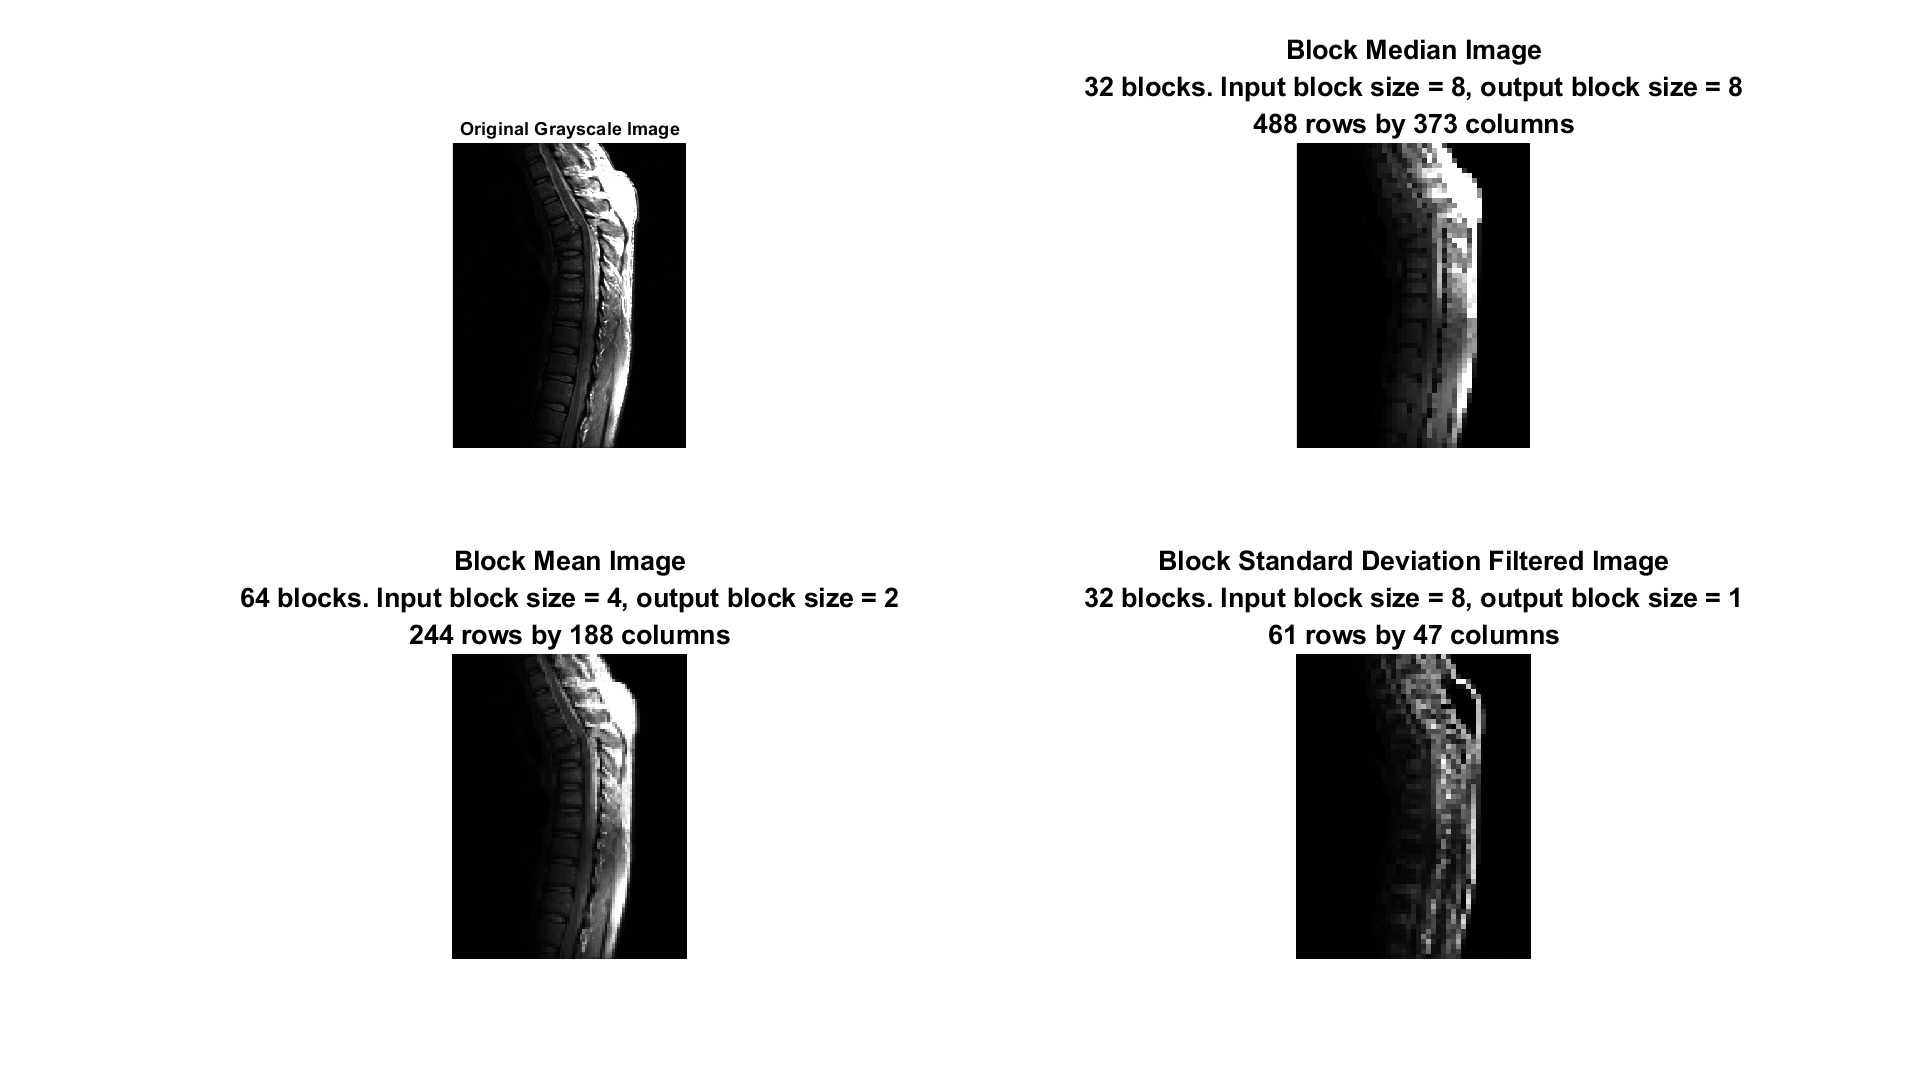

% Display the original gray scale image.
subplot(2, 2, 1);
imshow(grayImage, []);
title('Original Grayscale Image', 'FontSize', fontSize);
% Enlarge figure to full screen.
set(gcf, 'Position', get(0,'Screensize')); 
set(gcf,'name','Image Analysis Demo','numbertitle','off') 
% Define the function that we will apply to each block.
% First in this demo we will take the median gray value in the block
% and create an equal size block where all pixels have the median value.
% Image will be the same size since we are using ones() and so for each block
% there will be a block of 8 by 8 output pixels.
medianFilterFunction = @(theBlockStructure) median(theBlockStructure.data(:)) * ones(size(theBlockStructure.data), class(theBlockStructure.data));
% Block process the image to replace every pixel in the 
% 8 pixel by 8 pixel block by the median of the pixels in the block.
blockSize = [8 8];
% Quirk: must cast grayImage to single or double for it to work with median().
% blockyImage8 = blockproc(grayImage, blockSize, medianFilterFunction); % Doesn't work.
blockyImage8 = blockproc(single(grayImage), blockSize, medianFilterFunction); % Works.
[rows columns] = size(blockyImage8);
% Display the block median image.
subplot(2, 2, 2);
imshow(blockyImage8, []);
caption = sprintf('Block Median Image\n32 blocks. Input block size = 8, output block size = 8\n%d rows by %d columns', rows, columns);
title(caption, 'FontSize', fontSize);
% Block process the image to replace every pixel in the 
% 4 pixel by 4 pixel block by the mean of the pixels in the block.
% The image is 256 pixels across which will give 256/4 = 64 blocks.
% Note that the size of the output block (2 by 2) does not need to be the size of the input block!
% Image will be the 128 x 128 since we are using ones(2, 2) and so for each of the 64 blocks across
% there will be a block of 2 by 2 output pixels, giving an output size of 64*2 = 128.
% We will still have 64 blocks across but each block will only be 2 output pixels across,
% even though we moved in steps of 4 pixels across the input image.
meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:)) * ones(2,2, class(theBlockStructure.data));
blockSize = [4 4];
blockyImage64 = blockproc(grayImage, blockSize, meanFilterFunction);
[rows columns] = size(blockyImage64);
% Display the block mean image.
subplot(2, 2, 3);
imshow(blockyImage64, []);
caption = sprintf('Block Mean Image\n64 blocks. Input block size = 4, output block size = 2\n%d rows by %d columns', rows, columns);
title(caption, 'FontSize', fontSize);
% Block process the image to replace every pixel in the 
% 8 pixel by 8 pixel block by the standard deviation
% of the pixels in the block.
% Image will be smaller since we are not using ones() and so for each block
% there will be just one output pixel, not a block of 8 by 8 output pixels.
blockSize = [8 8];
StDevFilterFunction = @(theBlockStructure) std(double(theBlockStructure.data(:)));
blockyImageSD = blockproc(grayImage, blockSize, StDevFilterFunction);
[rows columns] = size(blockyImageSD);
% Display the block standard deviation filtered image.
subplot(2, 2, 4);
imshow(blockyImageSD, []);
title('Standard Deviation Filtered Image', 'FontSize', fontSize);
caption = sprintf('Block Standard Deviation Filtered Image\n32 blocks. Input block size = 8, output block size = 1\n%d rows by %d columns', rows, columns);
title(caption, 'FontSize', fontSize);